## Load the data set

load data_0to5_PBE.mat;

## Scattering map figure in linear scale

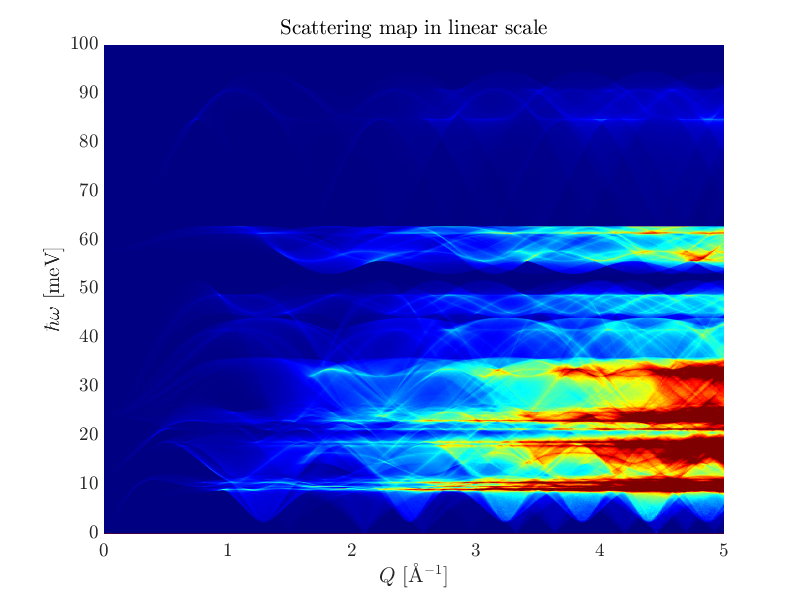

[XX,YY]=meshgrid(maps.q,maps.w);

f1=figure(1);
set(f1,'Position',[300 500 800 600]);
set(gcf,'color','w');

h=surf(XX,YY,maps.sum); view(0,90); caxis([0 0.02]);
set(h,'lines','none'); colormap(jet(256));

ylim([0 100]);
box on; grid off;

set(gca,'fontsize',14,'TickLabelInterpreter','latex','XMinorTick','on');
xlabel('$Q$~[\AA$^{-1}$]','interpreter','latex');
ylabel('$\hbar\omega$~[meV]','interpreter','latex');
title('Scattering map in linear scale','interpreter','latex');


% set(gcf,'Renderer','Painters');
% print(f1,'test','-depsc');

## Scattering map in log scale

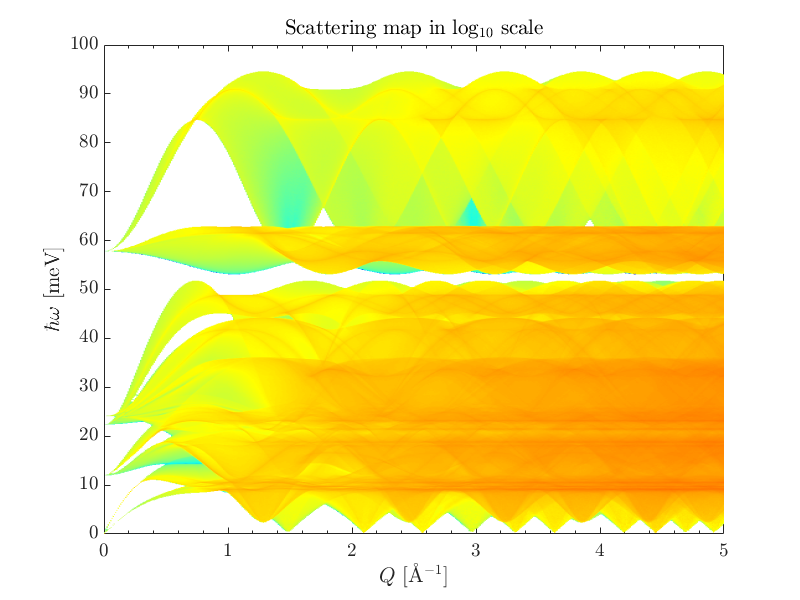

[XX,YY]=meshgrid(maps.q,maps.w);

f2=figure(2);
set(f2,'Position',[300 500 800 600]);
set(gcf,'color','w');

h=surf(XX,YY,real(log10(maps.sum))); view(0,90);
set(h,'lines','none'); colormap(jet(256));

ylim([0 100]);
box on; grid off;

set(gca,'fontsize',14,'TickLabelInterpreter','latex','XMinorTick','on');
xlabel('$Q$~[\AA$^{-1}$]','interpreter','latex');
ylabel('$\hbar\omega$~[meV]','interpreter','latex');
title('Scattering map in log$_{10}$ scale','interpreter','latex');


% set(gcf,'Renderer','Painters');
% print(f2,'test','-depsc');